# Sesion 1: Introducción a MATLAB

## Trabajando con MATLAB

En la práctica uno debe conocer

- Entorno de trabajo: ventana de comandos, workspace, barras de herramientas

- Editores de scripts: scripts, funciones, livescripts

- Fundamentos básicos

- IA de MATLAB

- Atajos de teclado

## Livescripts en MATLAB

### Características:

- Extensión .mlx (por ejemplo, Sesion`1_matlab.mlx`)

- Integra texto (Markdown) y comandos de MATLAB

- Organización por secciones

- Manejo de funciones de usuario en el mismo documento

### Atajos de teclado

- `Ctrl +`: Zoom

- `Ctrl + N`: Nuevo script

- `Ctrl + S`: Guardar script

- `Ctrl + Enter`: Ejecutar una sección

### Modo MATLAB

a=1000

a = 1000

A=[1 2; 
    2 1]

A =      1     2
     2     1


size(A)

ans =      2     2


A*A

ans =      5     4
     4     5


A^2

ans =      5     4
     4     5


### Modo texto: insertando una imagen

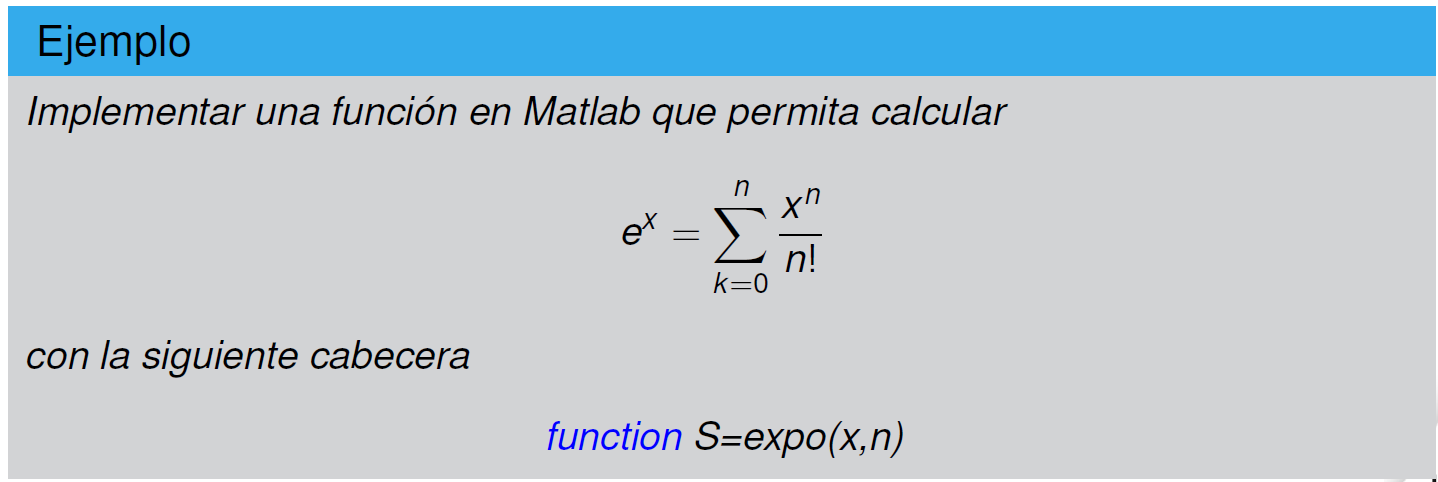

### Modo texto: insertando una ecuación

a) Tipear `$\delta$ `genera $\delta$

b) Tipear `$f(t)= \cos(\pi t)$` genera $f(t)=\cos(\pi t)$

c) Tipear

$

\left[

\begin{array}{ccc}

    1 & 2 & 3  \\

    1 & 2 & 3 

\end{array}

\right]

$ 

genera 


$$\left[
\begin{array}{ccc}
    1 & 2 & 3  \\
    1 & 2 & 3 
\end{array}
\right]$$


Averiguar sobre herramientas para LaTeX

- Overleaf: [https://www.overleaf.com/](https://www.overleaf.com/) 

- mathpix: [https://mathpix.com/](https://mathpix.com/)  

- chatGPT u otras IA's

## Practicando MATLAB

### Creación de funciones

- Ver el script `compute_square.m` en la misma carpeta de trabajo

A=10

A = 10

A^2

ans = 100

compute_square(A)

ans = 100

- Ver la función de usuario `error_rel` en el script Sesion1`_matlab.mlx`

A=1000 % valor exacto

A = 1000

a=1000.5 % valor aproximado

a = 1.0005e+03

error_rel(A,a)

ans = 5.0000e-04

error_relativo = error_rel(A,a)

error_relativo = 5.0000e-04

### IA de MATLAB

- [https://la.mathworks.com/matlabcentral/playground/new](https://la.mathworks.com/matlabcentral/playground/new) 

### Ejercicios:

**Ejercicio 1**: Encuentre una expresión *corta* en MATLAB para construir la matriz


$$B = \left[
\begin{array}{ccccccc}
1 & 2 & 3 & 4 & 5 & 6 & 7 \\
9 & 7 & 5 & 3 & 1 & -1 & -3 \\
4 & 8 & 16 & 32 & 64 & 128 & 256
\end{array} \right]$$


**Ejercicio 2**: Dé una expresión en MATLAB que use solamente una multiplicación de matrices con $B$ para obtener

a) la suma de las columnas 5 y 7 de $B$

b) la última fila de $B$

c) una versión de $B$ con las filas 2 y 3 intercambiadas

**Ejercicio 3**: Dé una expresión en MATLAB que multiplique dos vectores para obtener

a) la matriz $\left[
\begin{array}{ccccc}
    1 & 2 & 3 & 4 & 5 \\
    1 & 2 & 3 & 4 & 5 \\
    1 & 2 & 3 & 4 & 5
\end{array}
\right]$

b) la matriz $\left[
\begin{array}{ccc}
    0 & 0 & 0 \\
    1 & 1 & 1 \\
    2 & 2 & 2 \\
    3 & 3 & 3 \\
    4 & 4 & 4
\end{array}
\right]$

**Ejercicio 4**: Modifique la diapositiva 30 para producir tonos de frecuencia descendente en su lugar.

**Ejercicio 5**:

a) Escriba la función $g(t)$ que tiene la forma de una onda sinusoidal que aumenta linealmente en frecuencia desde 0 Hz en $t=0$ s hasta 5 Hz en $t=10$ s.

b) Trace el gráfico de esta función usando el comando `plot` de MATLAB.

Funciones de usuario:

function delta=error_rel(valor_exacto,valor_aprox)
% Doc de la función (ejercicio)

% el símbolo ; es para que no imprima en consola
delta = abs(valor_exacto-valor_aprox) / abs(valor_exacto);
end

function output_arg =compute_square( input_arg )
output_arg = input_arg .^ 2;
end